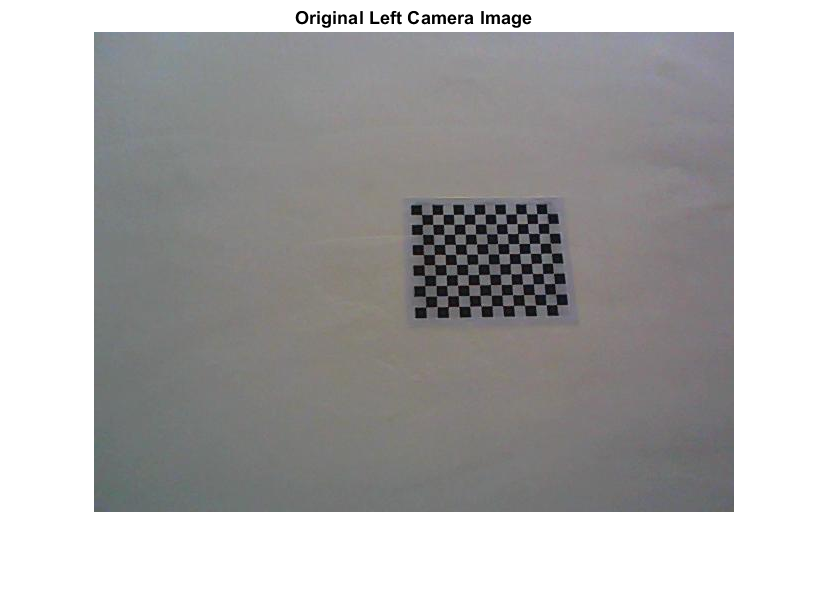

% Auto-generated by stereoCalibrator app on 26-Jul-2022
%-------------------------------------------------------


% Define images to process
checkerboardPatterns_left = imageDatastore("..\Stereo Images\webCam_left", "FileExtensions",'.jpg');
imageFileNames1 = checkerboardPatterns_left.Files;

%To see the readed image
img_1 = imread(imageFileNames1{1});
figure, imshow(img_1), title("Original Left Camera Image");

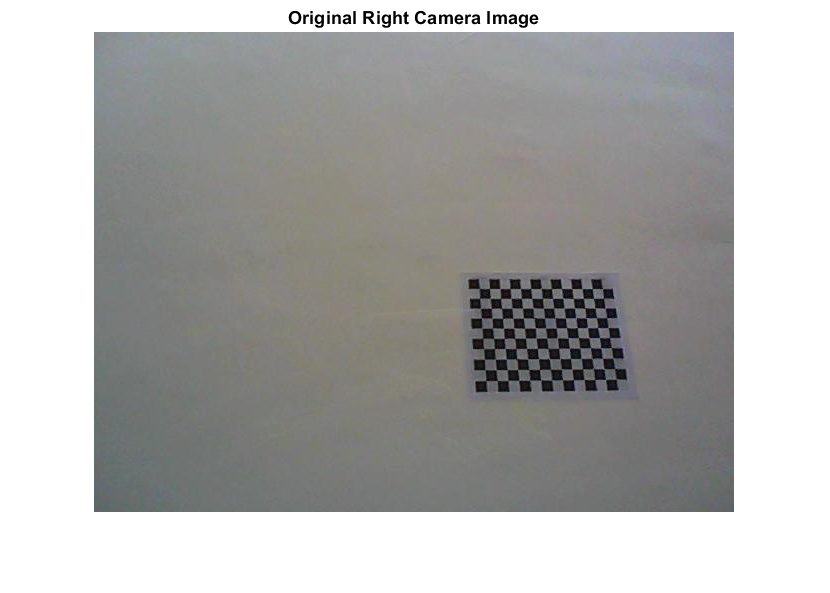

checkerboardPatterns_right = imageDatastore("..\Stereo Images\webCam_right", "FileExtensions",'.jpg');
imageFileNames2 = checkerboardPatterns_right.Files;

%To see the readed image
img_2 = imread(imageFileNames2{1});
figure, imshow(img_2), title("Original Right Camera Image");


% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames1, imageFileNames2);

% Generate world coordinates of the checkerboard keypoints
squareSize = 12;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Read one of the images from the first stereo pair
I1 = imread(imageFileNames1{1});
[mrows, ncols, ~] = size(I1);

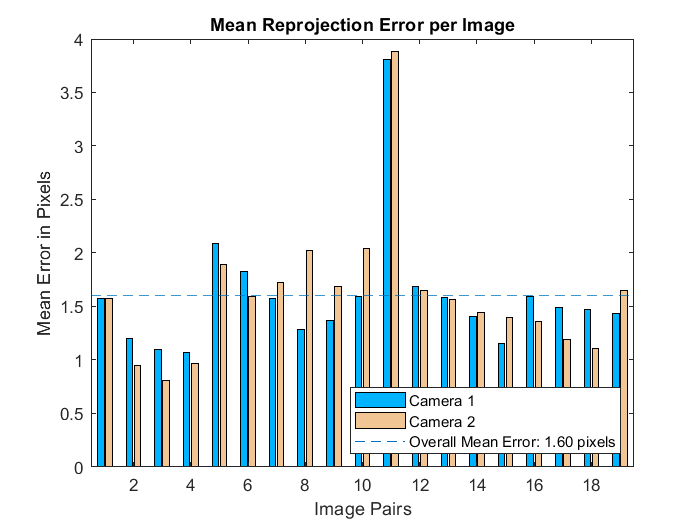

% Calibrate the camera
[stereoParams, pairsUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(stereoParams);

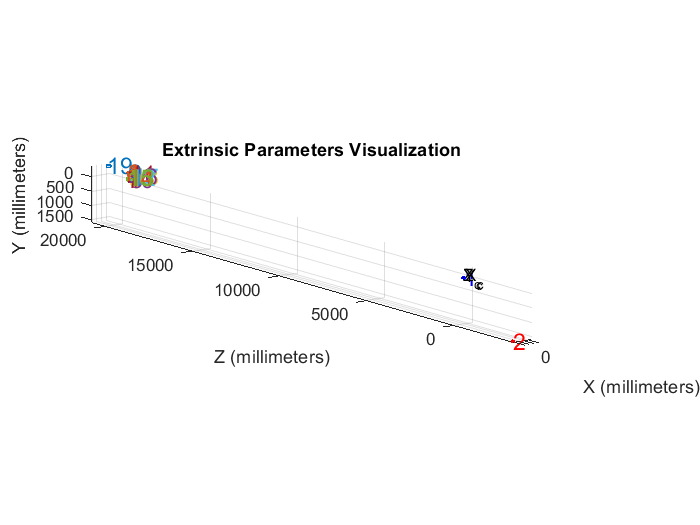


% Visualize pattern locations
h2=figure; showExtrinsics(stereoParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, stereoParams);


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [17983.9414 +/- 1318.5796 16636.9440 +/- 1211.7787]
Principal point (pixels):[  250.2761 +/- 5.6823      370.2262 +/- 10.4117 ]
Radial distortion:       [  136.0171 +/- 23.7272 39042.0248 +/- 20078.7079]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [   -0.2812 +/- 0.0079       -0.4297 +/- 0.0061       -0.0584 +/- 0.0018  ]
                         [   -0.2803 +/- 0.0091       -0.3323 +/- 0.0071       -0.0697 +/- 0.0017  ]
                         [   -0.2884 +/- 0.0093       -0.3130 +/- 0.0075       -0.0462 +/- 0.0017  ]
                         [   -0.3052 +/- 0.0091       -0.3215 +/- 0.0076       -0.0311 +/- 0.0018  ]
                         [   -0.2478 +/- 0.0081       -0.4280 +/- 0.0063       -0.0659 +/- 0.0018  ]
                         [   -0.2010 +/- 0.0081    

% Calculating Camera Parameters - Using images from one camera as both
% camera used for Stereo Calibration is same
I = readimage(checkerboardPatterns_left,1); 
imageSize = [size(I,1),size(I,2)];
params = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

% You can use the calibration data to rectify stereo images.
I2 = imread(imageFileNames2{1});
[J1, J2] = rectifyStereoImages(I1, I2, stereoParams);
% figure; imshow([J1, J2]), title("Stereo Calibrated:Left Camera ------- Right Camera");

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('StereoCalibrationAndSceneReconstructionExample')
% showdemo('DepthEstimationFromStereoVideoExample')

% References:

% [1] Z. Zhang. A flexible new technique for camera calibration. 
% IEEE Transactions on Pattern Analysis and Machine Intelligence, 
% 22(11):1330-1334, 2000.
% 
% [2] Janne Heikkila and Olli Silven. A Four-step Camera Calibration Procedure 
% with Implicit Image Correction, IEEE International Conference on Computer
% Vision and Pattern Recognition, 1997.
% 
% [3] Bouguet, JY. "Camera Calibration Toolbox for Matlab." 
% Computational Vision at the California Institute of Technology. 
% http://www.vision.caltech.edu/bouguetj/calib_doc/
% 
% [4] G. Bradski and A. Kaehler, "Learning OpenCV : Computer Vision with
% the OpenCV Library," O'Reilly, Sebastopol, CA, 2008.